I = 0.0050

I_w = 9.2875e-04

Parametros calculados:


I                = 0.00498000 kg.m^2


I_w              = 0.00092875 kg.m^2


omega_sem_carga  = 408.40704497 rad/s


k                = 0.02938245 V.s/rad


k_torque         = 0.02777778 N.m/A


r                = 7.05178825 ohm


Matriz A:


         0    1.0000         0
   98.1000         0    0.0246
         0         0   -0.1318



Matriz B:


         0
   -0.8367
    4.4863



Matriz C:


     1     0     0
     0     1     0
     0     0     1



Matriz D:


     0
     0
     0



Sistema em espaco de estados:



sys =
 
  A = 
            x1       x2       x3
   x1        0        1        0
   x2     98.1        0  0.02458
   x3        0        0  -0.1318
 
  B = 
            u1
   x1        0
   x2  -0.8367
   x3    4.486
 
  C = 
       x1  x2  x3
   y1   1   0   0
   y2   0   1   0
   y3   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
 
Continuous-time state-space model.


Matriz A aumentada:


         0    1.0000         0         0
   98.1000         0    0.0246         0
         0         0   -0.1318         0
         0         0   -1.0000         0



Matriz B aumentada:


         0
   -0.8367
    4.4863
         0



Posto da matriz de controlabilidade:


     4



Numero de estados do sistema aumentado:


     4



O sistema aumentado e controlavel.


Matriz Q inicial:


   32.8281         0         0         0
         0    0.9119         0         0
         0         0    0.0000         0
         0         0         0    0.0000



Matriz R inicial:


    0.0069



Ganho K do controlador LQR continuo:


 -263.4017  -28.1135   -0.1281    0.0120



Autovalores da malha fechada continua:


 -15.2488 + 0.0000i
  -7.4575 + 0.0000i
  -0.1864 + 0.1082i
  -0.1864 - 0.1082i



O sistema continuo em malha fechada e estavel.


Matriz Ad:


    1.0049    0.0100    0.0000         0
    0.9834    1.0049    0.0002         0
         0         0    0.9987         0
         0         0   -0.0100    1.0000



Matriz Bd:


   -0.0000
   -0.0084
    0.0448
   -0.0002



Ganho Kd do controlador LQR discreto:


 -247.8615  -26.3120   -0.1175    0.0107



Autovalores da malha fechada discreta:


   0.9981 + 0.0011i
   0.9981 - 0.0011i
   0.8585 + 0.0000i
   0.9281 + 0.0000i



O sistema discreto em malha fechada e estavel.


Autovalores da matriz A em malha aberta:


    9.9045
   -9.9045
   -0.1318



O modelo em malha aberta apresenta comportamento instavel.


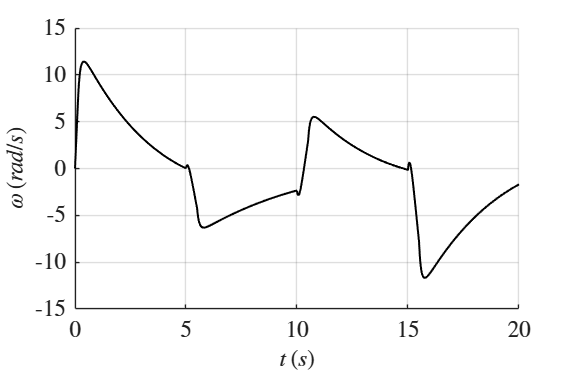

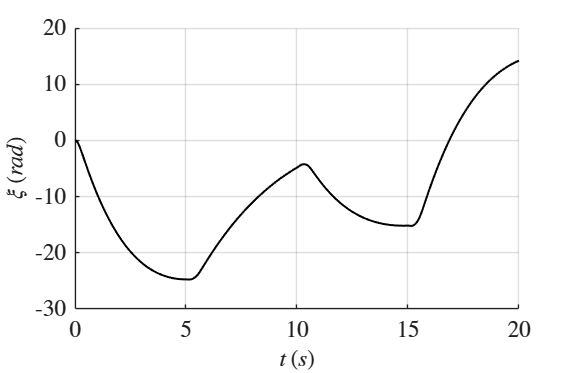

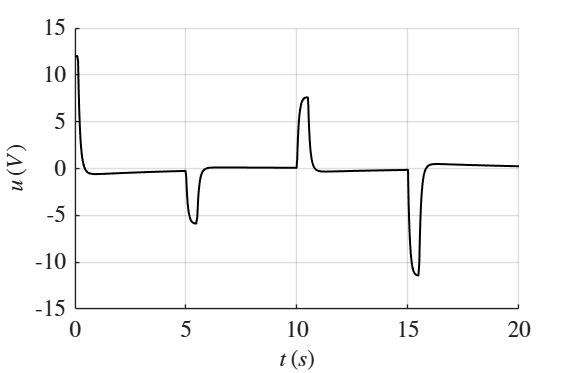

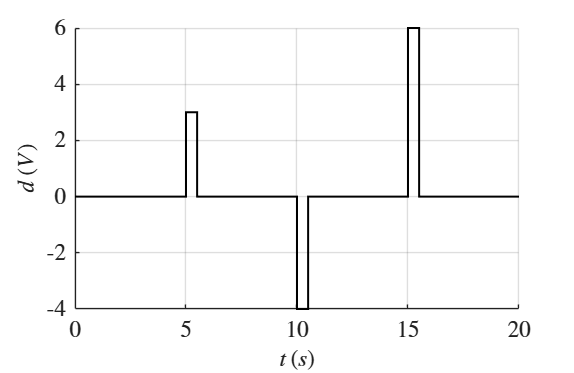

% =========================================================================
%  Modelagem, projeto do controlador LQR e validações numéricas
% =========================================================================
%
%  Este script reúne as principais etapas de modelagem e validação numérica
%  do triângulo autoequilibrante com roda de reação. O código calcula os
%  parâmetros físicos e eletromecânicos da planta, monta o modelo linear em
%  espaço de estados, inclui o estado adicional utilizado no controlador,
%  verifica a controlabilidade do sistema aumentado e projeta o controlador
%  LQR em tempo contínuo e discreto.
%
%  Também são realizadas duas validações numéricas. A primeira avalia o
%  comportamento da planta em malha aberta a partir de uma inclinação inicial
%  não nula, evidenciando a instabilidade natural do sistema. A segunda
%  avalia o desempenho do controlador LQR discreto em malha fechada, incluindo
%  distúrbios aplicados na entrada da planta.
%
%  O script gera os gráficos individuais em formato PDF para uso na
%  monografia, contemplando as respostas em malha aberta e em malha fechada.
%
%  Saídas geradas em malha aberta:
%    - validacao_theta_malha_aberta.pdf
%    - validacao_theta_dot_malha_aberta.pdf
%    - validacao_omega_malha_aberta.pdf
%
%  Saídas geradas em malha fechada:
%    - validacao_theta_malha_fechada.pdf
%    - validacao_theta_dot_malha_fechada.pdf
%    - validacao_omega_malha_fechada.pdf
%    - validacao_xi_malha_fechada.pdf
%    - validacao_controle_malha_fechada.pdf
%    - validacao_disturbios_malha_fechada.pdf
%
% =========================================================================

clc;
clear;
close all;

%% Modelo numérico em espaço de estados

% Estados:
% x1 = theta      [rad]
% x2 = theta_dot  [rad/s]
% x3 = omega      [rad/s]
%
% Entrada:
% u = V           [V]

%% Parâmetros físicos da estrutura

m = 0.498;          % massa do corpo [kg]
g = 9.81;           % aceleração da gravidade [m/s^2]
l = 0.10;           % distância do eixo de rotação ao centro de massa [m]

I = m*l^2;          % momento de inércia aproximado do corpo [kg.m^2]

%% Parâmetros da roda de reação

m_w = 0.117;        % massa da roda [kg]
R_w = 0.126;        % raio da roda [m]

I_w = 0.5*m_w*R_w^2;   % momento de inércia da roda como disco sólido [kg.m^2]

%% Parâmetros do motor Nidec 24H

V_nom = 12;            % tensão nominal [V]
I_nom = 0.9;           % corrente nominal [A]
tau_nom = 25e-3;       % torque nominal [N.m]
tau_stall = 50e-3;     % torque de travamento [N.m]
rpm_sem_carga = 3900;  % velocidade sem carga [rpm]

omega_sem_carga = rpm_sem_carga*2*pi/60;   % velocidade sem carga [rad/s]

k = V_nom/omega_sem_carga;                 % constante eletromecânica estimada [V.s/rad]

r = (k*V_nom)/tau_stall;                   % resistência estimada da armadura [ohm]

k_torque = tau_nom/I_nom;                  % constante de torque para comparação [N.m/A]

%% Modelo linear da planta

A = [0           1           0;
     m*g*l/I     0           k^2/(I*r);
     0           0          -k^2/(I_w*r)];

B = [0;
    -k/(I*r);
     k/(I_w*r)];

C = eye(3);
D = zeros(3,1);

sys = ss(A, B, C, D);

%% Exibição dos parâmetros e matrizes do modelo

disp('Parametros calculados:')
fprintf('I                = %.8f kg.m^2\n', I);
fprintf('I_w              = %.8f kg.m^2\n', I_w);
fprintf('omega_sem_carga  = %.8f rad/s\n', omega_sem_carga);
fprintf('k                = %.8f V.s/rad\n', k);
fprintf('k_torque         = %.8f N.m/A\n', k_torque);
fprintf('r                = %.8f ohm\n', r);

disp(' ')
disp('Matriz A:')
disp(A)

disp('Matriz B:')
disp(B)

disp('Matriz C:')
disp(C)

disp('Matriz D:')
disp(D)

disp('Sistema em espaco de estados:')
sys

%% Modelo aumentado com estado associado à roda

% Estado aumentado:
% xa = [theta; theta_dot; omega; xi]
%
% Dinâmica adicional:
% xi_dot = -omega

A_aug = [A              zeros(3,1);
         0   0   -1    0];

B_aug = [B;
         0];

C_aug = eye(4);
D_aug = zeros(4,1);

sys_aug = ss(A_aug, B_aug, C_aug, D_aug);

%% Verificação de controlabilidade

Co = ctrb(A_aug, B_aug);
posto_Co = rank(Co);
n_estados = size(A_aug,1);

disp('Matriz A aumentada:')
disp(A_aug)

disp('Matriz B aumentada:')
disp(B_aug)

disp('Posto da matriz de controlabilidade:')
disp(posto_Co)

disp('Numero de estados do sistema aumentado:')
disp(n_estados)

if posto_Co == n_estados
    disp('O sistema aumentado e controlavel.')
else
    disp('O sistema aumentado NAO e controlavel.')
end

%% Definição das matrizes Q e R pela regra de Bryson

theta_max = deg2rad(10);       % limite admissível para o ângulo [rad]
theta_dot_max = deg2rad(60);   % limite admissível para a velocidade angular [rad/s]
omega_max = 255;               % limite considerado para a velocidade da roda [rad/s]
xi_max = 1000;                 % limite considerado para o estado associado à roda

V_max = 12;                    % tensão máxima aplicada ao motor [V]

Q = diag([1/theta_max^2, ...
          1/theta_dot_max^2, ...
          1/omega_max^2, ...
          1/xi_max^2]);

R = 1/V_max^2;

disp('Matriz Q inicial:')
disp(Q)

disp('Matriz R inicial:')
disp(R)

%% Projeto do controlador LQR contínuo

K = lqr(A_aug, B_aug, Q, R);

disp('Ganho K do controlador LQR continuo:')
disp(K)

%% Análise da malha fechada contínua

A_cl = A_aug - B_aug*K;
eig_Acl = eig(A_cl);

disp('Autovalores da malha fechada continua:')
disp(eig_Acl)

if all(real(eig_Acl) < 0)
    disp('O sistema continuo em malha fechada e estavel.')
else
    disp('O sistema continuo em malha fechada NAO e estavel.')
end

%% Discretização do modelo aumentado

Ts = 0.01;   % tempo de amostragem [s]

sys_aug_d = c2d(sys_aug, Ts, 'tustin');

Ad = sys_aug_d.A;
Bd = sys_aug_d.B;
Cd = sys_aug_d.C;
Dd = sys_aug_d.D;

disp('Matriz Ad:')
disp(Ad)

disp('Matriz Bd:')
disp(Bd)

%% Projeto do controlador LQR discreto

Kd = dlqr(Ad, Bd, Q, R);

disp('Ganho Kd do controlador LQR discreto:')
disp(Kd)

%% Análise da malha fechada discreta

Ad_cl = Ad - Bd*Kd;
eig_Adcl = eig(Ad_cl);

disp('Autovalores da malha fechada discreta:')
disp(eig_Adcl)

if all(abs(eig_Adcl) < 1)
    disp('O sistema discreto em malha fechada e estavel.')
else
    disp('O sistema discreto em malha fechada NAO e estavel.')
end

%% Validação numérica da modelagem em malha aberta

eig_A = eig(A);

disp('Autovalores da matriz A em malha aberta:')
disp(eig_A)

if any(real(eig_A) > 0)
    disp('O modelo em malha aberta apresenta comportamento instavel.')
else
    disp('O modelo em malha aberta nao apresenta autovalores instaveis.')
end

%% Resposta livre em malha aberta

t = 0:0.001:1.0;
u = zeros(size(t));

% Condição inicial da planta:
% theta(0) = 5 graus
% theta_dot(0) = 0 rad/s
% omega(0) = 0 rad/s
x0 = [deg2rad(5); 0; 0];

[y, t, x] = lsim(sys, u, t, x0);

theta_graus = rad2deg(x(:,1));
theta_dot_graus = rad2deg(x(:,2));
omega_rad = x(:,3);

%% Figura 1 - Ângulo da planta em malha aberta

hfig = figure;

plot(t, theta_graus, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$\theta \, (^\circ)$', 'Interpreter', 'latex');

grid on;

fname = 'validacao_theta_malha_aberta';
picturewidth = 20;
hw_ratio = 0.65;

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

%% Figura 2 - Velocidade angular do corpo em malha aberta

hfig = figure;

plot(t, theta_dot_graus, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$\dot{\theta} \, (^\circ/s)$', 'Interpreter', 'latex');

grid on;

fname = 'validacao_theta_dot_malha_aberta';
picturewidth = 20;
hw_ratio = 0.65;

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

%% Figura 3 - Velocidade angular da roda em malha aberta

hfig = figure;

plot(t, omega_rad, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$\omega \, (rad/s)$', 'Interpreter', 'latex');

grid on;

fname = 'validacao_omega_malha_aberta';
picturewidth = 20;
hw_ratio = 0.65;

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

%% Validação numérica do controlador em malha fechada

t = 0:Ts:20;
N = length(t);

% Condição inicial da simulação em malha fechada:
% theta(0) = 5 graus
% theta_dot(0) = 0 rad/s
% omega(0) = 0 rad/s
% xi(0) = 0 rad
x0_cl = [deg2rad(5); 0; 0; 0];

x_cl = zeros(4, N);
u_cl = zeros(1, N);
d_cl = zeros(1, N);

x_cl(:,1) = x0_cl;

%% Definição dos distúrbios aplicados na entrada

for k = 1:N
    if t(k) >= 5 && t(k) < 5.5
        d_cl(k) = 3;
    elseif t(k) >= 10 && t(k) < 10.5
        d_cl(k) = -4;
    elseif t(k) >= 15 && t(k) < 15.5
        d_cl(k) = 6;
    end
end

%% Simulação discreta em malha fechada com distúrbios

for k = 1:N-1

    u_cl(k) = -Kd*x_cl(:,k);

    if u_cl(k) > 12
        u_cl(k) = 12;
    elseif u_cl(k) < -12
        u_cl(k) = -12;
    end

    x_cl(:,k+1) = Ad*x_cl(:,k) + Bd*(u_cl(k) + d_cl(k));
end

u_cl(N) = -Kd*x_cl(:,N);

if u_cl(N) > 12
    u_cl(N) = 12;
elseif u_cl(N) < -12
    u_cl(N) = -12;
end

%% Conversão dos estados para representação gráfica

theta_cl_graus = rad2deg(x_cl(1,:));
theta_dot_cl_graus = rad2deg(x_cl(2,:));
omega_cl = x_cl(3,:);
xi_cl = x_cl(4,:);

%% Figura 1 - Ângulo da planta em malha fechada

hfig = figure;

plot(t, theta_cl_graus, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$\theta \, (^\circ)$', 'Interpreter', 'latex');

grid on;

fname = 'validacao_theta_malha_fechada';
picturewidth = 20;
hw_ratio = 0.65;

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

%% Figura 2 - Velocidade angular do corpo em malha fechada

hfig = figure;

plot(t, theta_dot_cl_graus, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$\dot{\theta} \, (^\circ/s)$', 'Interpreter', 'latex');

grid on;

fname = 'validacao_theta_dot_malha_fechada';
picturewidth = 20;
hw_ratio = 0.65;

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

%% Figura 3 - Velocidade angular da roda em malha fechada

hfig = figure;

plot(t, omega_cl, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$\omega \, (rad/s)$', 'Interpreter', 'latex');

grid on;

fname = 'validacao_omega_malha_fechada';
picturewidth = 20;
hw_ratio = 0.65;

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

%% Figura 4 - Estado associado à posição acumulada da roda

hfig = figure;

plot(t, xi_cl, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$\xi \, (rad)$', 'Interpreter', 'latex');

grid on;

fname = 'validacao_xi_malha_fechada';
picturewidth = 20;
hw_ratio = 0.65;

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

%% Figura 5 - Sinal de controle em malha fechada

hfig = figure;

plot(t, u_cl, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$u \, (V)$', 'Interpreter', 'latex');

grid on;

fname = 'validacao_controle_malha_fechada';
picturewidth = 20;
hw_ratio = 0.65;

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

%% Figura 6 - Distúrbios aplicados na entrada

hfig = figure;

stairs(t, d_cl, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$d \, (V)$', 'Interpreter', 'latex');

grid on;

fname = 'validacao_disturbios_malha_fechada';
picturewidth = 20;
hw_ratio = 0.65;

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')